ScatterPlot and Graphs for distance versus correlation 

Set File Path and Read Excelsheet 

cd('C:\Users\khosh1\Dropbox\Leah\Leah-Doug a-syn paper\Data');

region = 'SNc' %SNc or VTA

region = 'SNc'

virus = 'asyn' %asyn or pff

virus = 'asyn'

condition = 'inj' %control or inj

condition = 'inj'

sheet = ['DC_' region '_' virus '_' condition]

sheet = 'DC_SNc_asyn_inj'

cellData= readtable('Network_analysis_Data_Supplemental.xlsx', 'UseExcel', true, 'Sheet', sheet); 
distance= cellData.Distance(2:end); 
correlation= cellData.Correlation(2:end);



Make ScatterPlot 

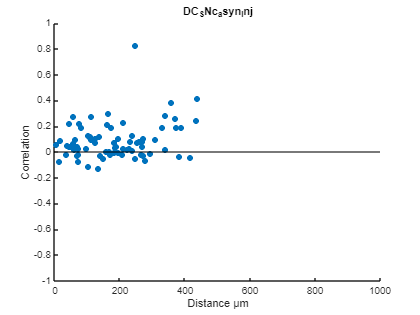

fitResult = fitlm(distance,correlation)
rSquared = fitResult.Rsquared

scatter (distance, correlation, "filled");
hold on 
yline(0, 'k');
title(sheet);
xlabel ('Distance µm');
ylabel ('Correlation');
ylim ([-1 1]);

xlim ([0 1000]);
hold off

fitResult = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat      pValue 
                   __________    __________    _______    ________

    (Intercept)      0.030762      0.031281    0.98342     0.32865
    x1             0.00030731    0.00014431     2.1295    0.036584


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 0.139
R-squared: 0.0585,  Adjusted R-Squared: 0.0456
F-statistic vs. constant model: 4.53, p-value = 0.0366

rSquared = struct with fields:
    Ordinary: 0.0585
    Adjusted: 0.0456


saveas (gcf, sheet, 'svg')